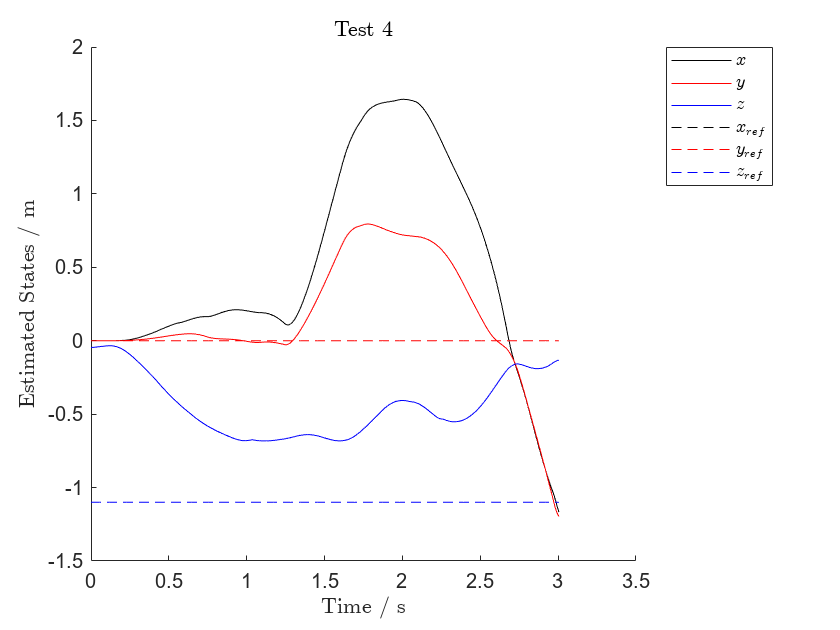

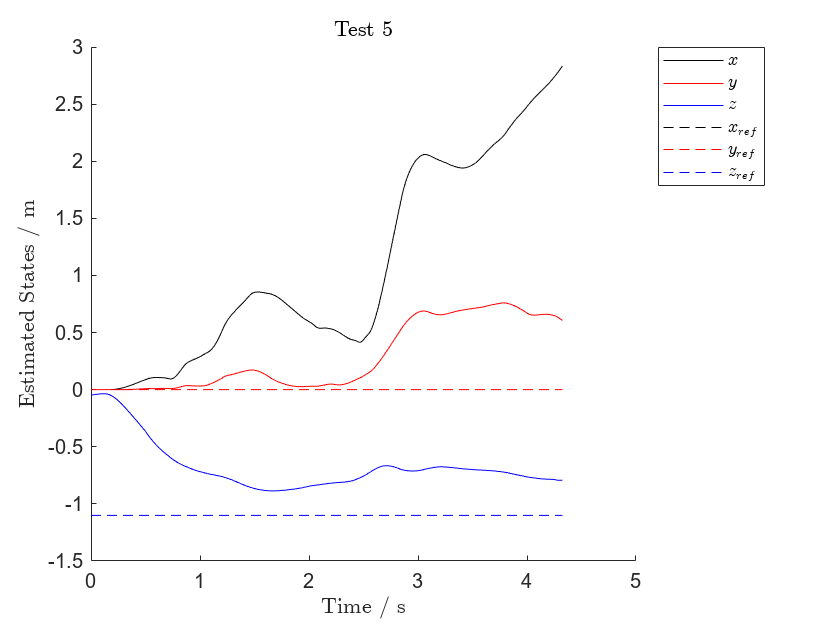

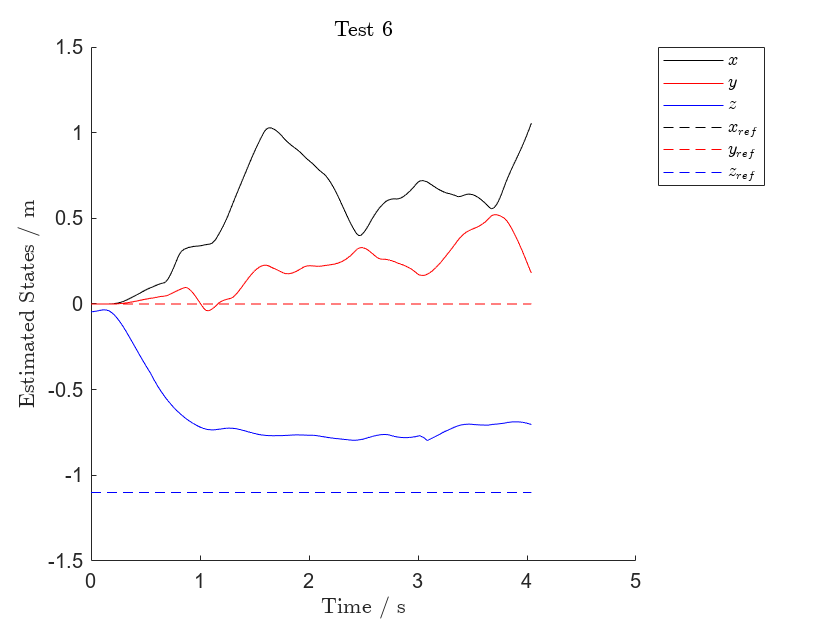

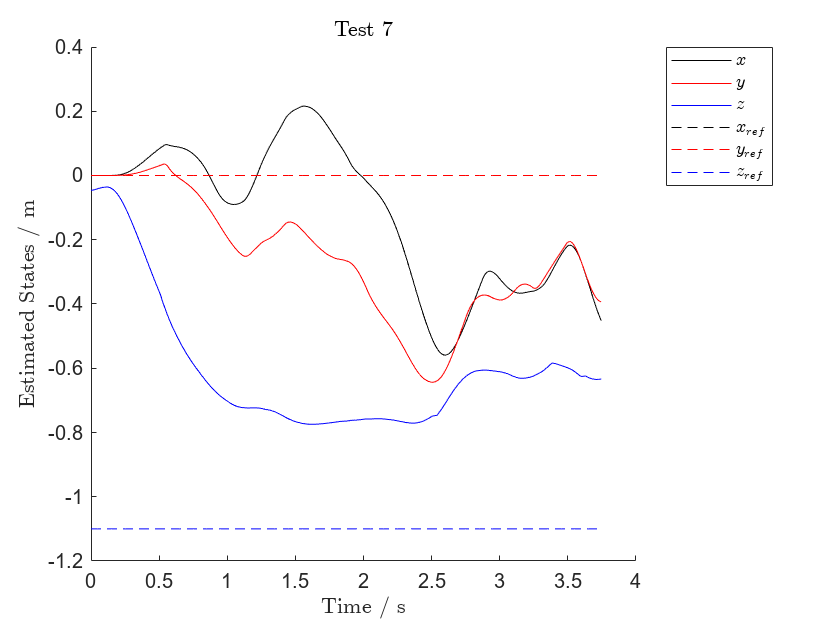

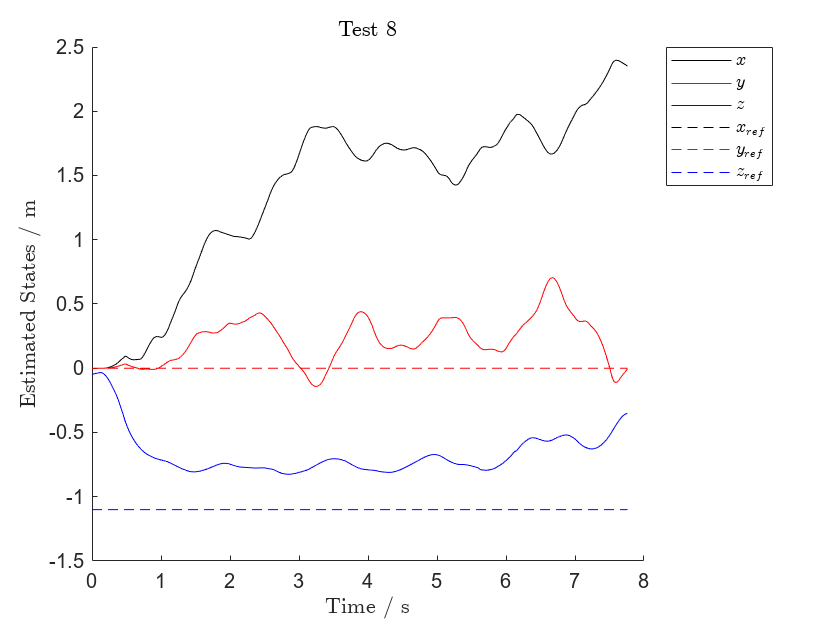

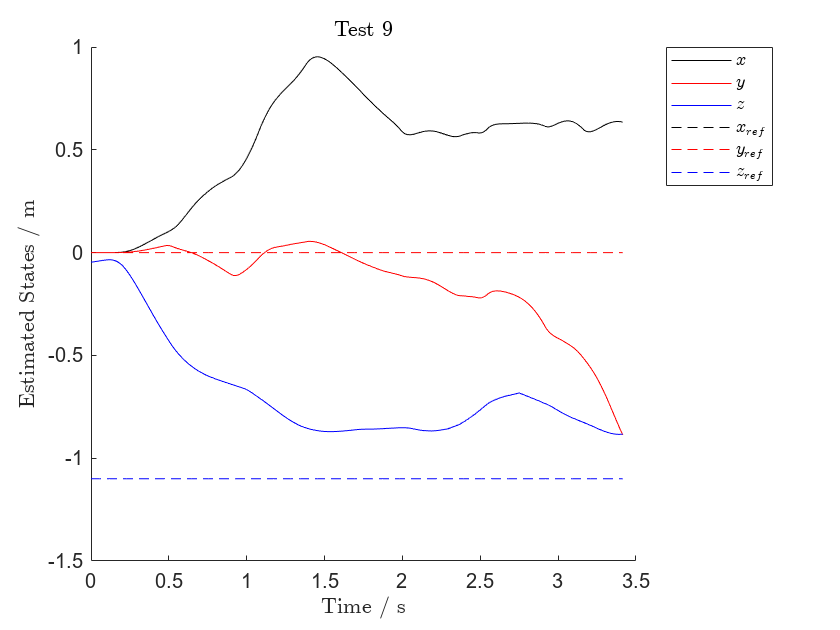

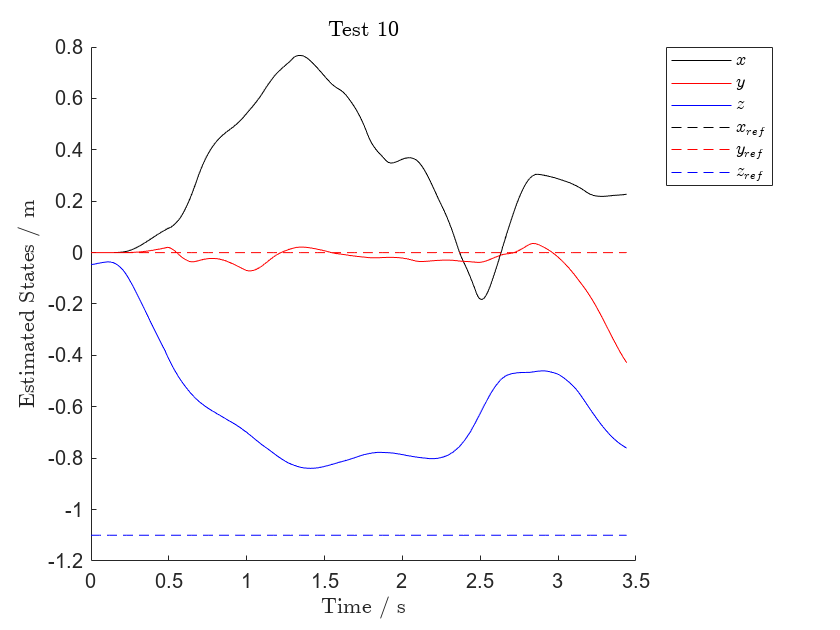

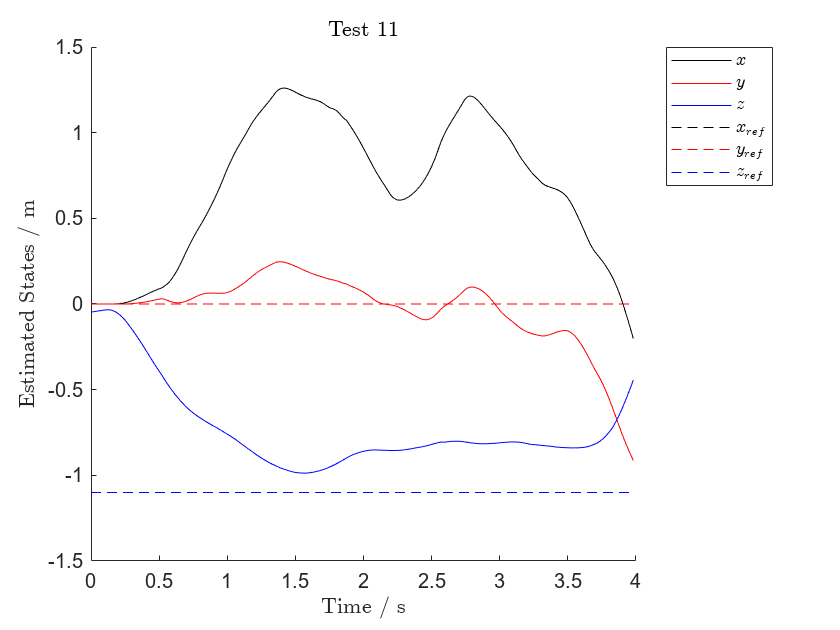

clear
clc
close all

for testNum = 1:22
    if any(testNum == [16 19 22 3 1 2])
        continue
    end
    % Generate the file name based on the current test number
    fileName = sprintf('Test%d.mat', testNum);
    
    % Load the file
    load(fileName);
    
    % Plotting
    figure;
    hold on
    plot(rt_estimatedStates.time, rt_estimatedStates.signals.values(:, 1),'k');
    plot(rt_estimatedStates.time, rt_estimatedStates.signals.values(:, 2),'r');
    plot(rt_estimatedStates.time, rt_estimatedStates.signals.values(:, 3),'b');
    plot(rt_reference.time, rt_reference.signals.values(:,1),'k--');
    plot(rt_reference.time, rt_reference.signals.values(:,2),'r--');
    plot(rt_reference.time, rt_reference.signals.values(:,3),'b--');
    hold off
    
    % Customize plot
    title(sprintf('Test %d', testNum),'Interpreter',"latex");
    xlabel('Time / s', 'Interpreter','latex');
    ylabel('Estimated States / m', 'Interpreter','latex');
    legend({'$x$', '$y$', '$z$','$x_{ref}$','$y_{ref}$','$z_{ref}$'}, 'Location','northeastoutside','Interpreter','latex');
    
    % Save the figure
    saveFileName = sprintf('Test%d.png', testNum); % Construct the filename for saving
    exportgraphics(gca, saveFileName, 'Resolution', 300); % Use exportgraphics for better quality
    
    % Optional: Close the figure after saving to manage memory usage
    close(gcf); % Uncomment this line if you want to automatically close the figure after saving
end